# Pdf and Cdf of Exponential RV

Note: this script reproduces the figure of the exponential RV in Section 2.2.4 of **Statistics for Chemical Engineers**, with realizations of Exp(4). Victor Z UW-Madison, 2020 compare exponential RVs

clc; clear all; close all hidden;

## Parameters

parameter values

beta=[1,2,4];
w=[0.5,1,1.5,2];
x=linspace(0,4,1000);
n=length(x);

## Realizations

generate realizations

S=1000;
rng(0);
X = exprnd(4,S,1);
figure(1)
subplot(2,2,[1 2])
plot(X,'blacko','MarkerFaceColor','w','MarkerSize',4)
xlabel('Outcome $\omega$','Interpreter','latex','FontSize',14)
ylabel('$x_\omega$','Interpreter','latex','FontSize',14)
grid on

figure(1)
subplot(2,2,3)
for k=1:length(beta)
plot(x,exppdf(x,beta(k)),'black','LineWidth',w(k))
hold on
end
grid on
xlabel('$x$','Interpreter','latex','FontSize',14)
ylabel('$f(x)$','Interpreter','latex','FontSize',14)
title('')

subplot(2,2,4)
for k=1:length(beta)
plot(x,expcdf(x,beta(k)),'black','LineWidth',w(k))
hold on
end
plot(x,ones(n,1)*0.63,'black--')
grid on
lgd=legend('$\beta=1$','$\beta=2$','$\beta=4$','Interpreter','latex','location','southeast')

lgd =   Legend ($\beta=1$, $\beta=2$, $\beta=4$) with properties:

         String: {'$\beta=1$'  '$\beta=2$'  '$\beta=4$'}
       Location: 'southeast'
    Orientation: 'vertical'
       FontSize: 7.6500e+00
       Position: [7.5558e-01 1.2955e-01 1.3566e-01 1.2154e-01]
          Units: 'normalized'

  Show all properties

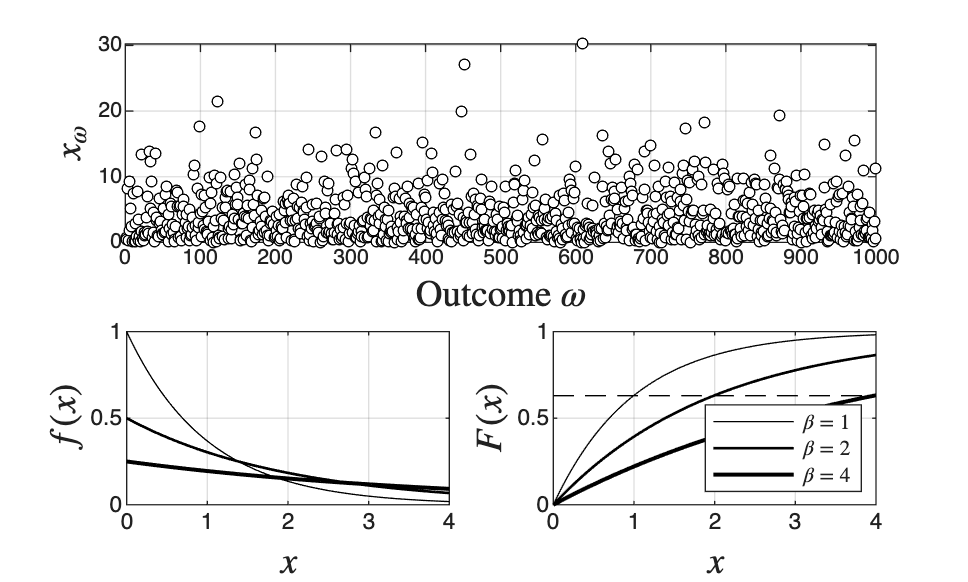

lgd.FontSize = 8;
xlabel('$x$','Interpreter','latex','FontSize',14)
ylabel('$F(x)$','Interpreter','latex','FontSize',14)
title('')
print -depsc ch2_compareexponentials.eps

## Note

The exponential RV models waiting times; its mean is the scale parameter beta.